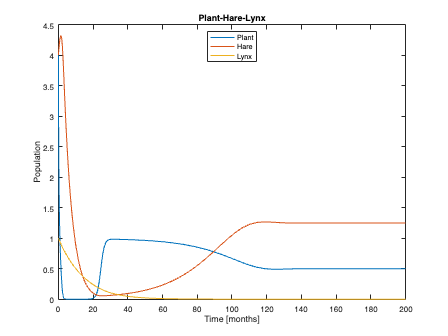

% Scenario 2 Description: The lynx population goes extinct (population very close to zero) after a year, plants and 
% hares stabilize within 120 months.


t0 = 0;             % Start time of simulation [in months]
tfinal = 200;       % End time of simulation [in months]
y0= [4 4 1];        % Initial state i.e. number of plants, hares and lynxs at t=0
tspan = [t0 tfinal];% Time span defined by the start and end times of the simulation [in months]
a1 = 1;             % Predation rate of the hares on the plants
a2 = 0.2;           % Predation rate of the lynxes on the hares 
b1 = 3;             % Saturation point of the hares when eating plants
b2 = 9;             % Saturation point of lynxes when eating hares
d1 = 0.2;           % Death rate of the hares
d2 = 0.09;          % Death rate of the lynxes

[t,y] = ode23(@(t,y) plants_hare_lynx_(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);


% Plotting the population over time for Scenario 3
figure("Name",'hare-lynx for S2');
plot(t,y)
title('Plant-Hare-Lynx Population over Time for Scenario 2');
xlabel('Time [months]');
ylabel('Population');
legend('Plant','Hare','Lynx','Location','North');

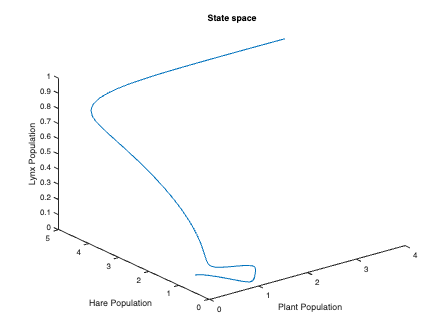

% Plotting the state-space diagram for Scenario 2
figure("Name",'State space for S2')
plot3(y(:,1),y(:,2),y(:,3))
title('State-space Diagram for Scenario 2')
xlabel('Plant Population')
ylabel('Hare Population')
zlabel('Lynx Population')